# Assignment 6, ENGS 27 Summer 2023 Solutions

## Problem 1A

for this problem, we first make an absorbing node for when a transmission succeeds, and 7 nodes representing 0-6 transmissions. after we use the formula for time to be absowrbed.

format long
k = 1:7;

e = 0.9-0.05*k; %array for probabilities

matrix = zeros(8);

matrix(1,1) = 1;
matrix(8,2) = e(7);
for i = 1:7
    if i<7
    matrix(i+1,i+2) = e(i); %probability of failing
    end
    
    matrix(i+1,1) = 1 - e(i); % probability of succeeding
end


B = matrix(2:8,2:8);
P1A = (eye(7)-B)\ones(7,1); %formula for wait time to be absorbed
P1A(1)

ans =    4.080771173789707


## Problem 1B

for this problem we use a similar process as part A, but we instead multiply by the respective delay times of each transmission

B = matrix(2:8,2:8);
P1B = (eye(7)-B)\[0 1 2 3 4 5 6]';
P1B(1)

ans =    7.757686478630877


## Problem 2A

There are two slightly different answers for part A, but depending on if you use the matlab function or do the slides will change your answer.

P = [0 .06 .9  .03 .01  0;
     0 .1 .8  .09 .01  0;
     0 .03 .6  .34 .02 .01;
     0  0  .03 .9  .03 .04;
     0  0   0   0   0   1;
     0  0   0   0   0   1];

mc = dtmc(P);
ht = hittime(mc,"6"); %matlab function
P2A = ht(1)

P2A =   17.799896462467654


P2 = P([6 1 2 3 4 5],[6 1 2 3 4 5]);
B = P2(2:6,2:6)

B =                    0   0.060000000000000   0.900000000000000   0.030000000000000   0.010000000000000
                   0   0.100000000000000   0.800000000000000   0.090000000000000   0.010000000000000
                   0   0.030000000000000   0.600000000000000   0.340000000000000   0.020000000000000
                   0                   0   0.030000000000000   0.900000000000000   0.030000000000000
                   0                   0                   0                   0                   0


P2Aalt = (eye(5)-B)\ones(5,1);
P2Aalt(1) %from the slides for long it takes before being absorbed

ans =   17.799896462467654


## Problem 2B

For this problem we use the same formula as above but add the incomes instead to see what the expected lifetime salary after college is.


P2B = (eye(5)-B)\[0 12000 104000 340000 20000000]';
P2B(1)

ans =      1.386929076790337e+07


## Problem 2C

We use the formula (I-P)^-1 to get the expected number of visits to j after visiting I.


P2C = (eye(5)-B)^-1;

%multiply by salary to see future earnings
P2C(3,4)*340000

ans =      4.312338222605696e+06


## Problem 3A

for this problem we just use the formula for expected number of students in a time interval.

lambda = 10; %students in an hour
mu = 12; 
P3A = lambda/(mu-lambda)

P3A =      5


## Problem 3B

Wait time is 1/mu-lambda. we get 30 mins

1/(mu-lambda)*60 %answer is in hours, so we can convert to mins by *60

ans =     30


## Problem 3C

it would be a bad Idea because if the service rate isnt higher than the arrival rate then the queue probably won't ever be empty and cause lots of backlog.

## Problem 4A

we just plot the formula of Pn = (1-lambda/mu)*(lambda/mu)^n. but loop it from 0 to 50.

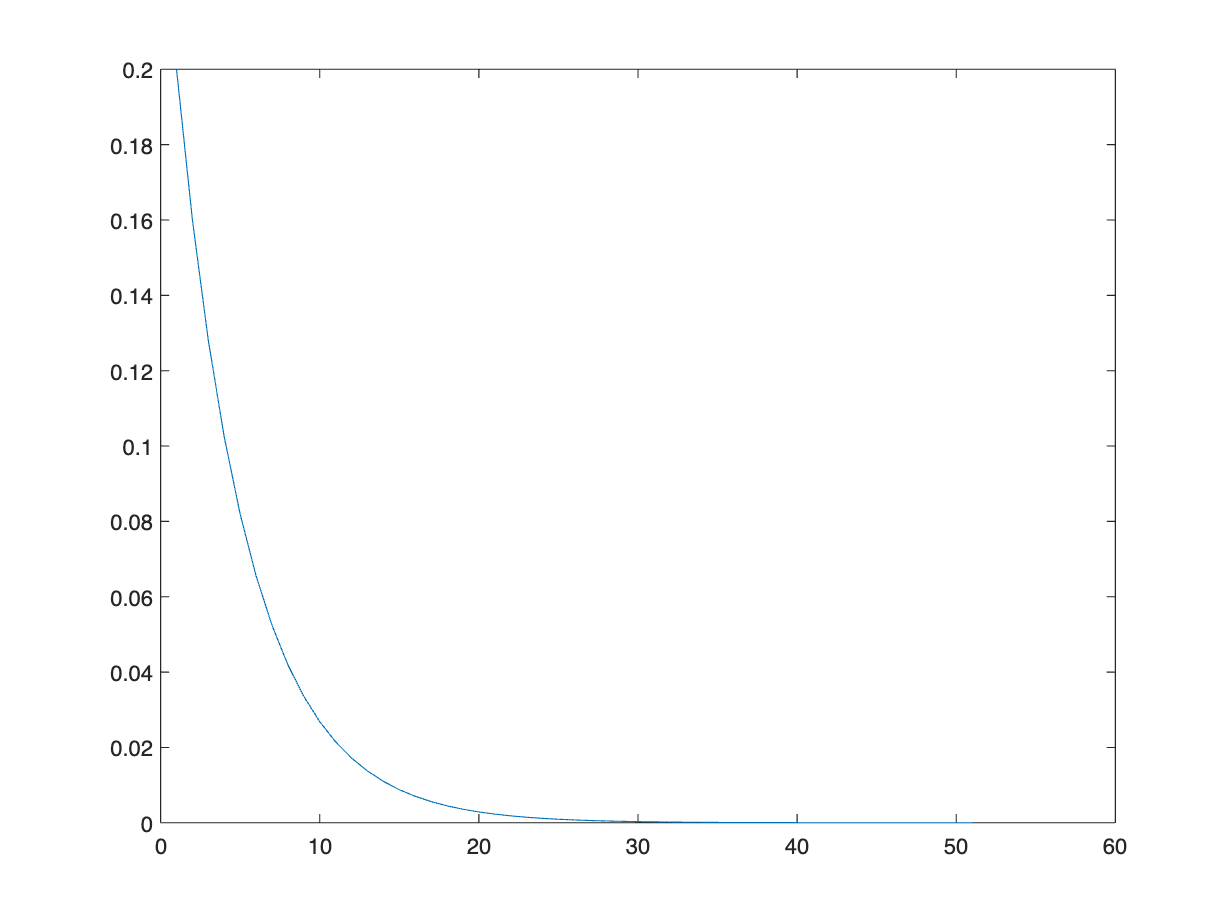

lambda = 40; % per hour
mu = 50;

for i= 0:50
    probs(i+1) = (1-lambda/mu)*(lambda/mu)^i;
end
plot(probs)

## Problem 4B

expected number in system is same formula as before

P4B = lambda/(mu-lambda)

P4B =      4


## Problem 4C

expected time in system is same as before

P4C = 1/(mu-lambda)*60 %to get in minutes

P4C =      6


## Problem 4D

for 4D we have to make the process of modeling the line increasing, decreasing, and staying the same. but when greater than 2 people in line we replace the arrival rate with the balkrate.

%defining time
t = 10^-6;
lambda = 4;
mu = 5;
Pa0 = 1-lambda*t; % prob 0 arrivals
Pa1 = lambda*t; % prob 1 arrival
Pd0 = 1 - mu*t; % prob 0 departures
Pd1 = mu*t; % prob 1 arrival


ProbMat(1,1) = Pa0;
ProbMat(1,2) = Pa1;

for i = 2:10
    if i>3
        balkrate = 4/(i-3); % to match indexing
        Pa0 = 1-balkrate*t; % prob 0 arrivals replaced
        Pa1 = balkrate*t; % prob 1 arrival replaced
        ProbMat(i,i-1) = Pa0 * Pd1;
        ProbMat(i,i) = Pa0 * Pd0 + Pa1 * Pd1;
        ProbMat(i,i+1) = Pa1 * Pd0;
    else
     ProbMat(i,i-1) = Pa0 * Pd1;
    ProbMat(i,i) = Pa0 * Pd0 + Pa1 * Pd1;
    ProbMat(i,i+1) = Pa1 * Pd0;
    end
end

ProbMat(11,11) = 1-Pd1;
ProbMat(11,10) = Pd1;


P4D = asymptotics(dtmc(ProbMat))

P4D =    0.279370260489150   0.223497102382465   0.178797503105748   0.143037859434533   0.114429944258347   0.045771809881215   0.012205767131789   0.002441143180508   0.000390581213420   0.000052077265262   0.000005951657564


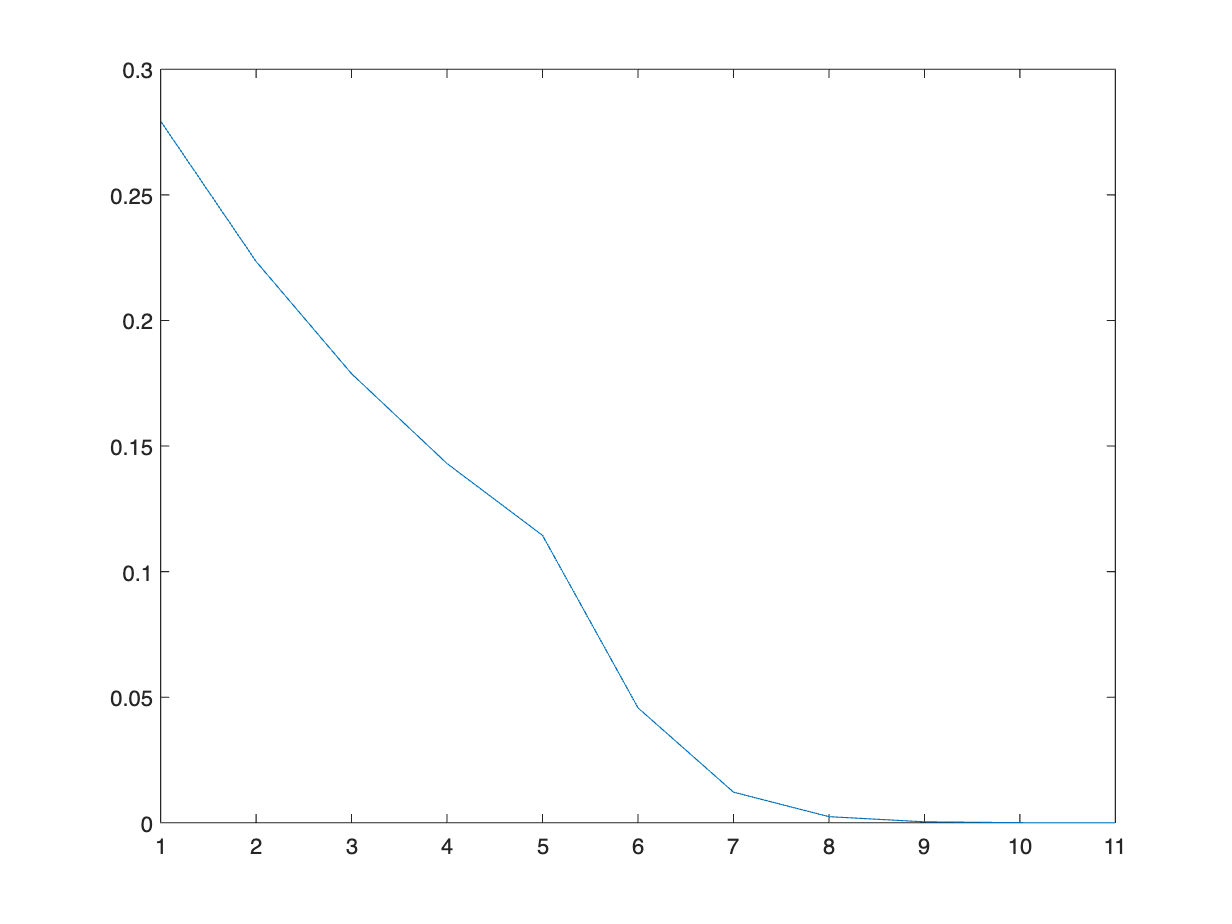

plot(P4D)

% plot stationary distribution 
ExpectedValue = sum(P4D.*[0:10]) % expected value sum(Sd(x)*x)

ExpectedValue =    1.790759980061669


for i = 1:11
 tip(i) = 4/(i); % indexing
end
ExpectedTip = sum(P4D.*tip) %same as before but instead you multiply by tip

ExpectedTip =    2.076360154752403
